# ** Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

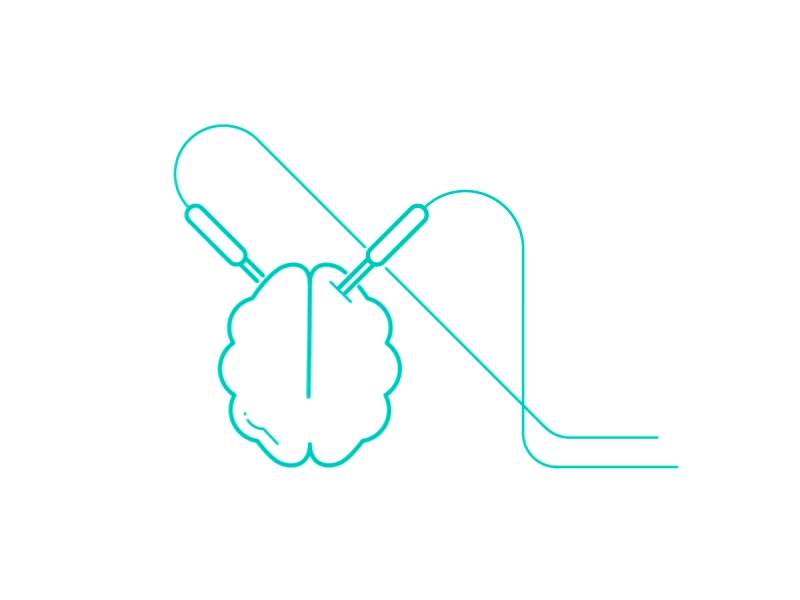

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\John\Desktop\data\raw\All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 2 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = true ;
Deci.DCom               = false ;
Deci.GCom               = false ; % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\John\Desktop\data\raw\AllProcessed'];        % Output Folder Directory

## 1. Trial Definitions 

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                         % Cell Array of Markers for End codes.
Deci.DT.FixUnevenStartEnd = true;
%                       ss1 ss2 ss4  L  R   Cor Incor
% Deci.DT.Markers    = {[52 53 54] [61 62] [64 65]};

Deci.DT.Markers    = {[11 21 31] [25 35] [39] [43] [52 53 54] [61 62] [64 65]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [50 58];  %add probe image on/offset for RT lock                                                              % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 5];    %[-2 5]                                                                % Time of Interest, be sure to include larger window for freq

Deci.DT.Block.Markers   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.1 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'no';
Deci.PP.denoiser = false;

Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.ATR =  false;
Deci.Art.AutomatedTR = true;
Deci.ICA.Automatic = true;

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 0];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [3 2];

Deci.Art.ShowArt = true;
Deci.Art.AddComponents =  false;

## 4. Analysis

AnalysisTypes = {'DMSS_Delay'};

AnalysisList = [true ];

## 5. Plotting

## ** 6. Run**

if Deci.Step == 4
    for AnalysisLocks = find(AnalysisList)
        Deci_Wavelet;
        
        Deci.Analysis.Freq.foi           = exp(linspace(log(3),log(60),40));  %change to 80                        % Frequency of Interest
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));   % Width
        Deci.Analysis.Toi           = [-.5 3];                                % [-.5 5]                  % Time Range to save
        Deci.Analysis.Toilim        = [-2 5]; %[-2 5]
        
        eval(AnalysisTypes{AnalysisLocks})
        Deci.SubjectList        = 'gui';
        Deci.Analysis.Freq.do  = true;
        Deci.Analysis.ERP.do  = false;
        Deci_Backend(Deci);
        
    end
else
    
    DMSS_Delay;
    
    Deci.Run.Behavior = false;
    Deci.Run.Freq =true;
    Deci.Run.ERP =false;
    Deci.Run.Extra = false; % for model, double, triplet, 2std
    
    Deci.Plot.BslRef =  'Delay Onset';
    Deci.Plot.Lock =  'Delay Onset';
    Deci.Plot.FreqYScale = 'linear';
    
    Deci.Plot.GrandAverage = true;
    Deci.Plot.GroupLevel =  false;
    Deci.Plot.Groups = {~[1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0] logical([1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0])};
    
    
    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [2.5 3];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.MTopo.do    =false;
    Deci.Plot.MTopo.Foi     = [12 21];                   % Frequency of Interest
    Deci.Plot.MTopo.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.MTopo.ToiSegs = 6;
    Deci.Plot.MTopo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =false;
    Deci.Plot.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.Square.Channel = [{'PO3'}];                % Channel of Interest
    
    Deci.Plot.Wire.do    =true;
    Deci.Plot.Wire.Foi     =   [3 inf];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [0 .5];                   % Time of Interest
    Deci.Plot.Wire.Channel = [{'PO3'}];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [30 80];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     =  [.5 3];                   % Time of Interest
    Deci.Plot.Bar.Channel =  [{'P6' 'P8' 'PO8'}];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        %Deci.Plot.Bsl     = [-.5 -.3]; -.250 -.050
        Deci.Plot.Bsl     = [-.5 -.2];
    else
      %  Deci.Plot.Bsl     = [-.5 -.2];
        Deci.Plot.Bsl     = [-.2 0];
        
    end
    
    if strcmpi(Deci.Plot.Freq.Type,'ITPC')
        Deci.Plot.Freq.Roi = 'maxmin';
    end
    
    Deci.Plot.ColorMap = fliplr(brewermap(255,'spectral')')';
    
    if Deci.Run.Extra
        Deci.Plot.BslType = 'relchange';
        Deci.Plot.Roi = 'maxmin';
        Deci.Plot.Stat.do = true;
       
        
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'no';
        %         Omnibus = true;
        %
        %
        %         if Omnibus == true
        %             Deci.Plot.Stat.do = true;
        %             Deci.Plot.Stat.Comp = 'Bsl';
        %             Deci.Plot.Stat.alpha = .01;
        %             Deci.Plot.Stat.correctm = 'fdr';
        %             Deci.Plot.BslType = 'relchange';
        %             Deci.Plot.Stat.FPlots =  false;
        %         else
        %             Deci.Plot.Stat.do = true;
        %             Deci.Plot.Stat.Type = 'Randomize Permutation';
        %             Deci.Plot.Stat.alpha = .05;
        %             Deci.Plot.Stat.correctm = 'fdr';
        %         end
        %         Deci.Plot.Stat.FPlots =  false;
        
        
        
    elseif  Deci.Plot.Square.do
        Omnibus = false;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'relchange';
            Deci.Plot.Stat.Type = 'Anova/T-test';
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
            Deci.Plot.Stat.correctm = 'fdr';
            %Deci.Plot.BslType ='relchange';
        end
        Deci.Plot.Stat.FPlots =  false;
    
    elseif Deci.Plot.Topo.do || Deci.Plot.MTopo.do
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
           % Deci.Plot.BslType ='db';
         %   Deci.Plot.Roi = [-1 1];
        end
    elseif Deci.Plot.Bar.do
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.FPlots =  false;
    elseif Deci.Plot.Wire.do
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.FPlots =  false;
        Deci.Plot.Stat.correctm = 'fdr';
         Deci.Plot.BslType ='relative';
    elseif Deci.Run.Extra
        Deci.Plot.BslType ='relchange';
    end
    
    Deci.Plot.Stat.twoway.do  = false;
    Deci.Whatever =  false;
    
 %   time = {[0 .5] [.5 1] [1 1.5] [1.5 2] [2 2.5] [2.5 3]};
%    for i = 1:length(time)
 %       Deci.Plot.MTopo.Toi = time{i};
%        Deci_Backend(Deci);
%    end
    
    Deci_Backend(Deci);
end

Running Deci for 34 subjects
 
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 36).
